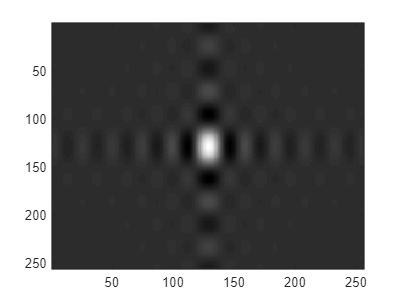

load ImagesTPTS;


ftrect1=fftshift(fft2(Rect1));
mrect1=abs(ftrect1);
Rrect=real(ftrect1);
Irect=imag(ftrect1);
Arect=angle(ftrect1);
imagesc(Rrect);

'^ partie réelle de la TF de rect1'

ans = '^ partie réelle de la TF de rect1'

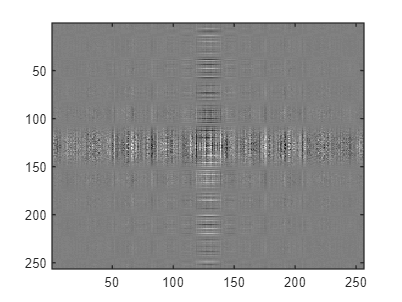

imagesc(Irect);

'^ partie imaginaire de la TF de rect1'

ans = '^ partie imaginaire de la TF de rect1'

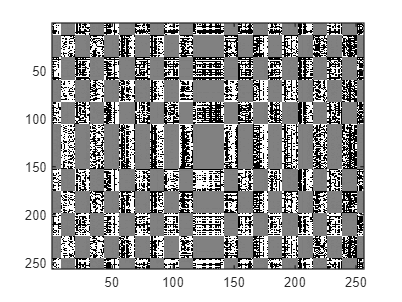

imagesc(Arect);

'^ phase de la TF de rect1'

ans = '^ phase de la TF de rect1'

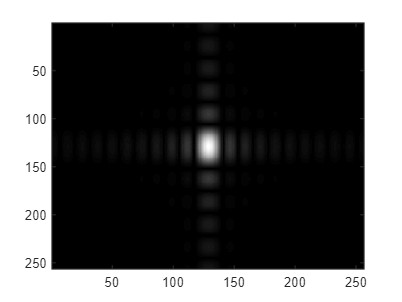

imagesc(mrect1);

'^ module de la TF de rect1'

ans = '^ module de la TF de rect1'

On reconnait le produit des sinus cardinaux en x et y

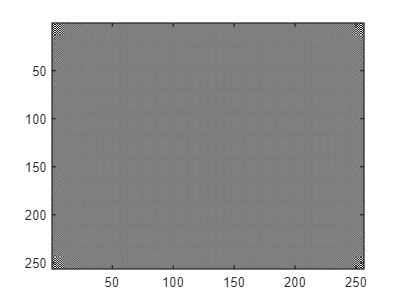

rect=fft2(fftshift(Rect1));
mrect=abs(rect);
Rrect=real(rect);
Irect=imag(rect);
Arect=angle(rect);
imagesc(Rrect);

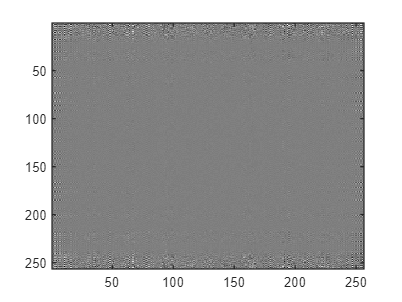

imagesc(Irect);

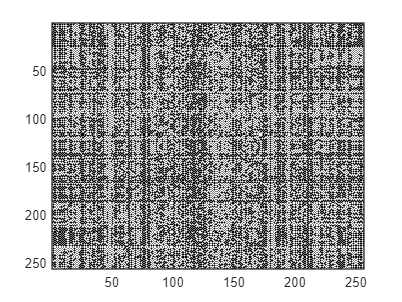

imagesc(Arect);

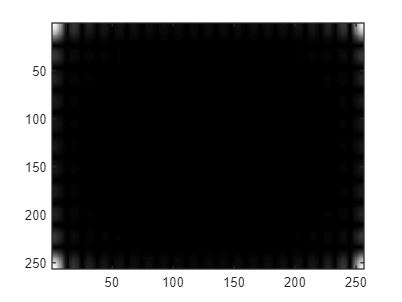

imagesc(mrect);

Le décalage crée une modulation par une exponentielle dans l'espace des phase

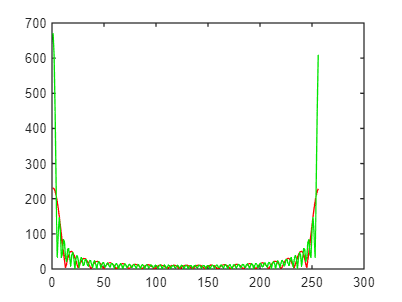

ftrect2=fft2(Rect2);
smrect1=ifftshift(mrect1);
smrect2=abs(ftrect2);
plot(smrect1(1,:))
hold on
plot(smrect2(1,:))
hold off

"^comparaison entre les modules des TF des deux Rect"

Le rect le plus étroit à une TF la plus large

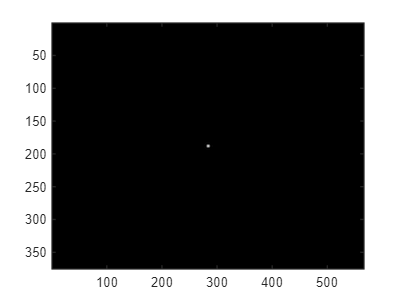

palaiseau=double(imread('Palaiseau.bmp'));

imagesc(fftshift(PSF));

"^ PSF"

ans = "^ PSF"

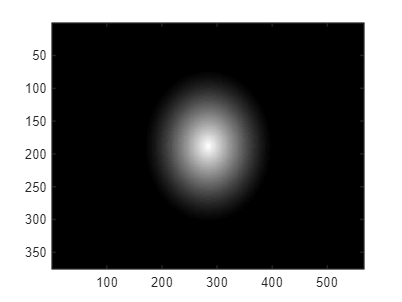

imagesc(fftshift(abs(fft2(PSF))));

"^ autocorrélation de la pupille"

ans = "^ autocorrélation de la pupille"

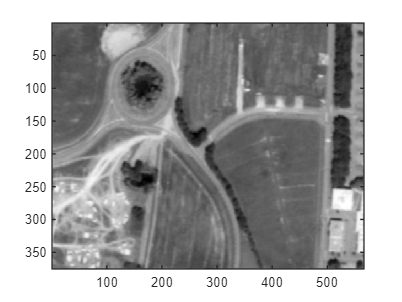

imagesc(Tfconvolution(PSF,palaiseau));
colormap("gray")

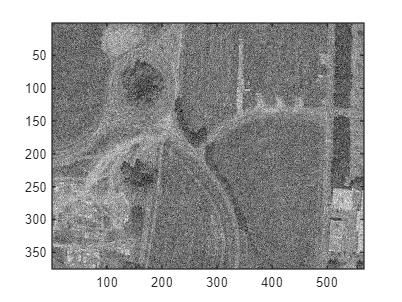

imagesc(BruitImage(palaiseau,0))

"^image bruitée"

ans = "^image bruitée"

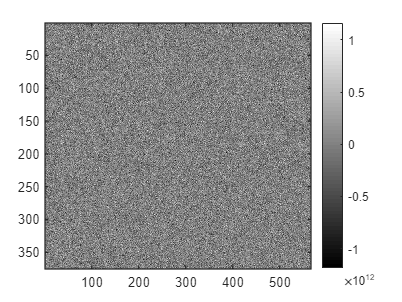

y0=Tfconvolution(PSF,palaiseau);
y1=BruitImage(y0,40);
yb=FiltreInverse(PSF,y1);
imagesc(yb);
colorbar;

"^filtre inverse"

ans = "^filtre inverse"

que du bruit (et d'ordre de 10^12)

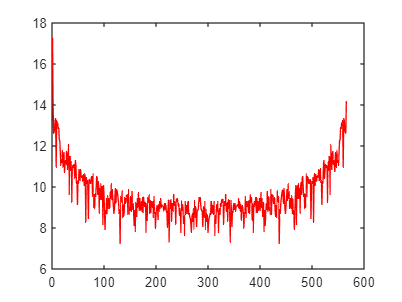

lpalaiseau=log(abs(fft2(palaiseau)));
ly0=log(abs(fft2(y0)));
lyb=log(abs(fft2(yb)));
linversePSF=log(abs(1./fft2(PSF)));
plot(lpalaiseau(1,:));

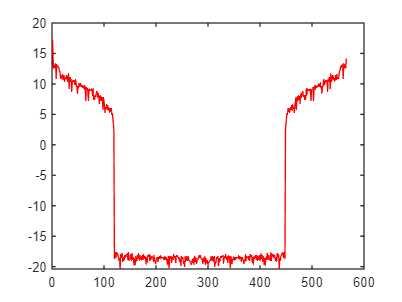

"densité spectrale de puissance (DSP) du signal"
plot(ly0(1,:));

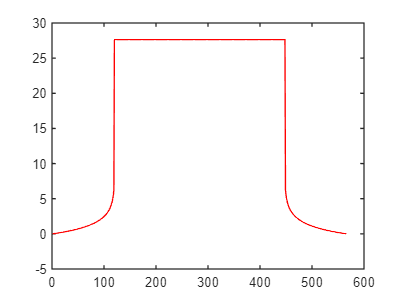

"DSP du signal filtré (descend jusqu'à la précision de calcul eps=2.2e-16)"
plot(linversePSF(1,:));

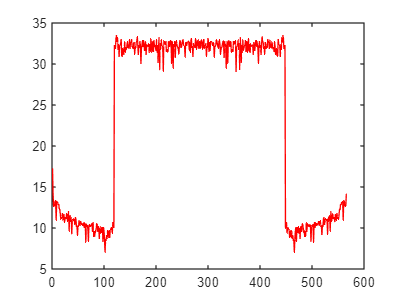

"module de la TF du filtre inverse: amplifie de 2e16 aux hautes fréquences"
plot(lyb(1,:));

"DSP du signal filtré, bruité, puis passé par le filtre inverse"

On voit comment le bruit se fait amplifier

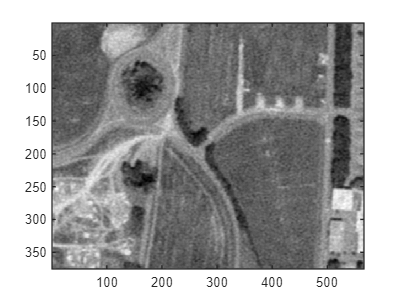

y0=Tfconvolution(PSF,palaiseau);
y1=BruitImage(y0,5);
yb=FiltreWiener(PSF,y1,10^-0.5);
imagesc(yb);

"traitement par filtre de Wiener"

ans = "traitement par filtre de Wiener"

Le filtre de Wiener évite l'amplification infnie du bruit

textefloute=double(imread("texte_Gr2.tif"))

textefloute =    251   249   251   246   251   250   248   251   248   251   249   249   248   249   250   249   248   249   248   250   249   250   249   251   249   251   251   251   248   249   250   248   251   251   249   250   248   251   251   247   250   248   248   251   249   249   249   250   251   249
   251   249   251   248   252   249   249   249   246   251   250   250   250   251   250   251   250   250   248   250   251   248   251   250   250   248   252   250   250   248   250   249   249   251   249   248   249   249   250   247   250   249   250   249   249   249   247   249   249   251
   247   249   250   248   250   247   250   250   251   246   250   250   250   250   248   248   248   251   250   248   251   248   249   251   250   249   251   249   245   250   250   250   249   250   250   248   248   249   251   249   250   248   248   249   249   249   250   250   251   250
   249   250   249   250   250   249   249   250   250   248   250   249   250   25

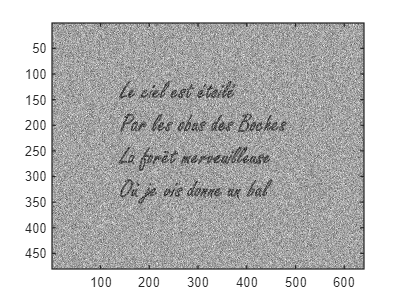


h=zeros(480,640);
h(1,1:25)=1;
h(1,640-24:640)=1;

textenet=FiltreWiener(h,textefloute,1/50);
imagesc(textenet)